# Shaw-Pierre example

We consider the three-degree-of-freedom mechanical system, which consists of the system studied by Shaw and Pierre [1], with an additional damper connecting the left mass to the wall, mounted on an oscillating cart, as in Haller and Kaundinya [2]. Here we use the coordinates $y_1 = q_1$, $y_2 = q_2 - q_1$ and $x_f$. 

[1]  S. Shaw and C. Pierre. Normal modes for non-linear vibratory systems. J. Sound Vib., 164(1): 85–124, 1993. 

[2] G. Haller and R. S. Kaundinya. Nonlinear Model Reduction to Temporally Aperiodic Spectral Submanifolds. Chaos. 34, 2024.

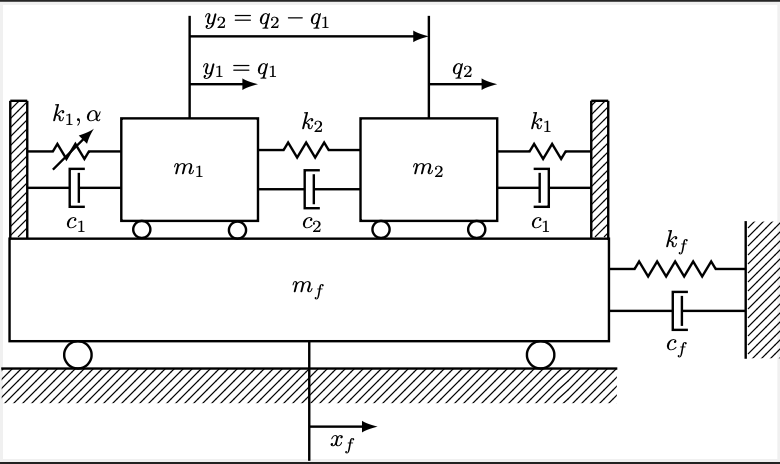

clearvars
close all

## Example setup

The governing equations are


$$\mathbf{M}\mathbf{\ddot{y}} + \mathbf{C}\mathbf{\dot{y}} + \mathbf{K}\mathbf{y} + \mathbf{f}_\mathrm{nl} = \mathbf{0},$$


with $ \mathbf{y} = \left(y_1,\, y_2, x_f \right)^\mathrm{T}$ and 


$$\mathbf{M} = \left[ \begin{array}{cc}
    m_1 & 0 & m_1\\
    m_2 & m_2 & m_2\\
0 & 0 & m_f
\end{array} \right],\quad
 \mathbf{C} = \left[ \begin{array}{cc}
    c_1 & -c_2 & 0\\
    c_1 & c_1 + c_2 & 0 \\
-2c_1 & -c_1 & c_f
   \end{array} \right],\quad
\mathbf{K} = \left[ \begin{array}{cc}
    k_1 & -k_2 & 0\\
    k _1& k_1 + k_2 & 0 \\
-2 k_1 & -k_1 & k_f
 \end{array} \right],\quad
\mathbf{f}_\mathrm{nl} = \left[ \begin{array}{cc}
    -\alpha y_1^3 \\
    0 \\
-\alpha y_1^3
     \end{array} \right].$$


k1 = 1;
k2 = 3 + 0.325;
c1 = 0.05;
alpha = 0.5;
factor = @(beta_alpha) 1/2 * beta_alpha;
c2_fun = @(beta_alpha) c1 * factor(beta_alpha);
beta_alpha_red = 0.4;
c2 = c2_fun(beta_alpha_red);
m_f = 1;
k_f = k2*10;
c_f = c2;
[F,A,M,C,K,F_nl] = SP_moving_frame(k1,k2,c1,c2,m_f,c_f,k_f,alpha);

T_tilde = [1 0 0; -1 1 0; 0 0 1];
M_t = M/T_tilde;
C_t = C/T_tilde;
K_t = K/T_tilde;

T = [1 0 0 0 0 0; -1 1 0 0 0 0; 0 0 1 0 0 0; 0 0 0 1 0 0; 0 0 0 -1 1 0; 0 0 0 0 0 1];
A_t = T*A/T;
F_t = @(t,eta) A_t * eta + T*F_nl(t,T\eta);
[V_t,D_t,lambda_t] = eigSorted(A_t);

**Preliminary analysis**

We approximate the primary SSM from SSMTool and compare trajectories lying on the primary and fractional SSMs. Compute the backbone curves. If the initial condition lies outside the primary SSM (on a fractional SSM), then its evolution in time develops oscillations in the backbone curve.

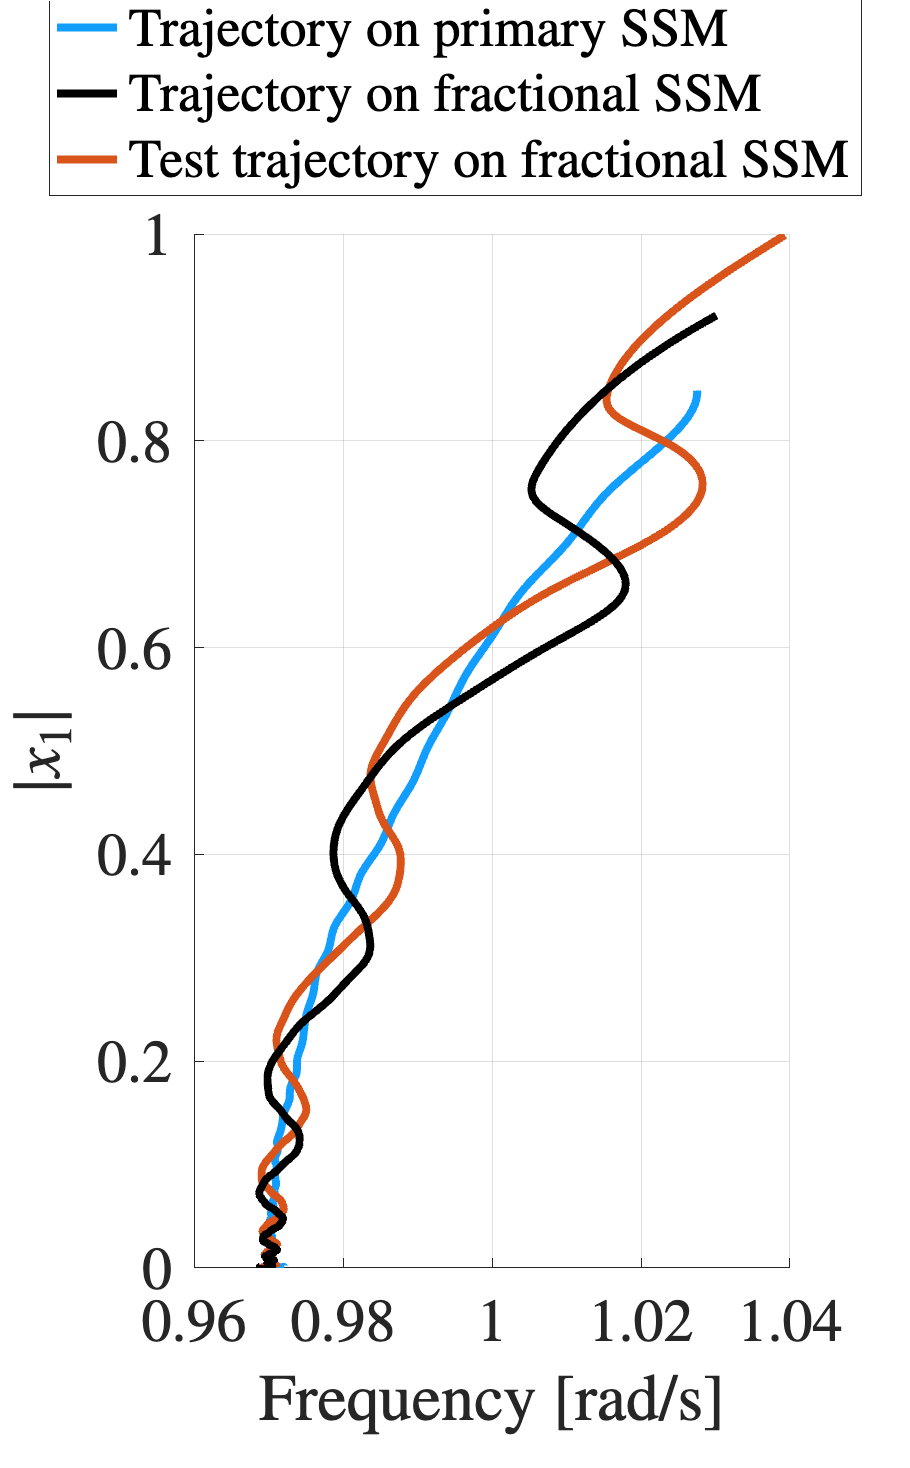

tSpan_decay = linspace(0,400,1e4);
[t_t, x_t, t_t_off, x_t_off, x0_ssm_t, t_t_train2, x_t_train2, t_t_test, x_t_test] = plot_SSMTool(F_t,tSpan_decay,V_t);

kmean = 1;       
[amp_ssm,freq_ssm,damp_ssm,time_ssm] = PFFk(t_t,x_t(1,:),kmean);
[amp_off,freq_off,damp_off,time_off] = PFFk(t_t_off,x_t_off(1,:),kmean);
[amp_test,freq_test,damp_test,time_test] = PFFk(t_t_test,x_t_test(1,:),kmean);

lim = 1e-3;
[freq_spline_ssm, amp_spline_ssm] = bc_spline(freq_ssm, amp_ssm, lim);
[freq_spline_off, amp_spline_off] = bc_spline(freq_off, amp_off, lim);
[freq_spline_test, amp_spline_test] = bc_spline(freq_test, amp_test, lim);

f = figure;
f.Position = [1028,132,455,734];
hold on 
grid on 
plot(freq_spline_ssm, amp_spline_ssm,'color',[0.07,0.62,1.00],'LineWidth',4,'DisplayName','Trajectory on primary SSM')
plot(freq_spline_off, amp_spline_off,'-k','LineWidth',4,'DisplayName','Trajectory on fractional SSM')
plot(freq_spline_test, amp_spline_test,'color',[0.85,0.33,0.10],'LineWidth',4,'DisplayName','Test trajectory on fractional SSM')

xlim([0.96 1.04])
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('$|x_1|$','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelinterpreter','latex')
h = get(gca,'Children');
set(gca,'Children',[h(2) h(1) h(3)], ...
    'OuterPosition',[0.017728508304763,0.021298756734844,0.930686947207466,0.884089825128026], ...
    'InnerPosition',[0.213186813186813,0.136557610241821,0.654945054945055,0.704041844799051], ...
    'Position',[0.213186813186813,0.136557610241821,0.654945054945055,0.704041844799051]);
legend([h(3) h(2) h(1)],'Location','NW','Interpreter','latex','Position',[0.075229572070824,0.889168935736186,0.850496061555631,0.09441417049647])


xData = cell(1,2);
xData{1,1} = t_t_off;
xData{1,2} = x_t_off;
xData{2,1} = t_t_train2;
xData{2,2} = x_t_train2;

xOutput = @(x) x(1,:);
endTime = xData{1,1}(end);



## Oblique projection and delay embedding 

We compute the linear oblique projection that best approximates the direction of the fast subspace from data. Obliquely projected coordinates serve as the reduced coordinates for the SSM parametrization, when the linear part of the dynamical system is non-normal. This procedure is strictly valid for oscillatory systems. The linear approximation of the projection is most accurate when computed from the linear regime of the data. In the suboptimal case when the linear regime of the data is unknown, the oblique projection is automatically computed across the entire data range.

Set $\texttt{oblique\_projection = false}$ in order to apply the standard normal projection. 

SSMDim = 2;
sliceInt = [10, endTime];

overEmbed = 0;
ShiftStep = 1;
oblique_projection = true;

lim = 2e-7; 
indStartTime = regimeLinear(xData,lim);

[yData, P, V_trunc_slow,data_non_projected,data_non_projected_trunc] = obliqueProjection(xData,indStartTime,SSMDim, overEmbed, ShiftStep, 'flag_end',0,'oblique_projection',oblique_projection);

The embedding coordinates consist of the measured states.
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0          13         0.127259                         0.394
     1          26        0.0234925              1          0.144  
     2          52       0.00429099        0.49802          0.012  
     3          65       0.00407528              1         0.0116  
     4          78       0.00330978              1         0.0124  
     5          91      0.000774001              1         0.0249  
     6         104      0.000321928              1         0.0168  
     7         117      0.000158249              1        0.00472  
     8         130      0.000144631              1        0.00126  
     9         143      0.000141681              1        0.00124  
    10         156      0.000111832              1        0.00258  
    11         169      6.80523e-05              1        0


xData_test = cell(1,2);
xData_test{1,1} = t_t_test;
xData_test{1,2} = x_t_test;

[yData_test, ~]= coordinatesEmbedding(xData_test,SSMDim,'OverEmbedding',overEmbed,'ShiftSteps',ShiftStep);

The embedding coordinates consist of the measured states.


data_non_projected{3,1} = yData_test{1,1};
data_non_projected{3,2} = yData_test{1,2};
yData_test{1,2} = P*yData_test{1,2};

yData{3,1} = yData_test{1,1};
yData{3,2} = yData_test{1,2};

The function $\texttt{obliqueProjection}$ also arranges the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space. The dimensionality of the observable space can be further expanded with the parameter `overEmbed` to facilitate recognition of the manifold from data.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

## SSM model reduction

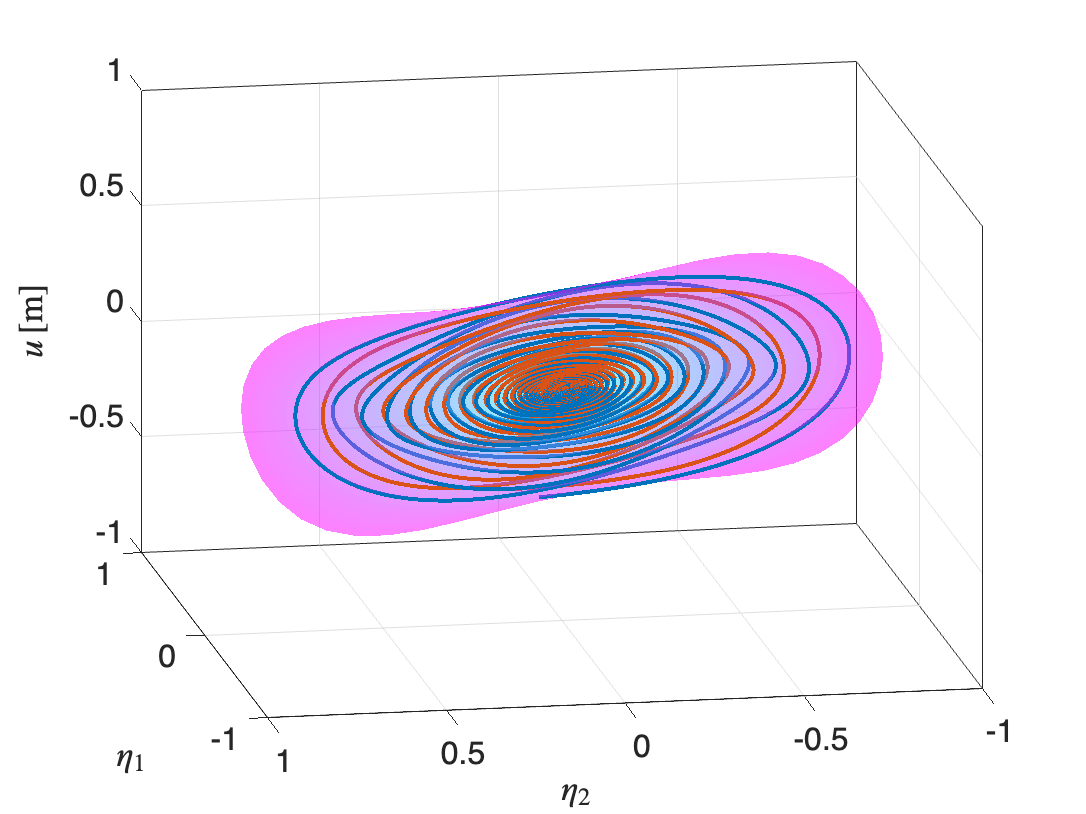

yDataTrunc = sliceTrajectories(yData, sliceInt);

indTrain = [1 2];
indTest = 3;

% manifold parametrization
SSMOrder = 5;

% compute the reduced coordinates as the oblique projection of the
% coordinates in the full observable space onto the slow subspace 

[IMInfo, ~, ~] = IMGeometry(yDataTrunc(indTrain,:), SSMDim, 1,'V_e',V_trunc_slow);
SSMChart_P = @(x) IMInfo.parametrization.tangentSpaceAtOrigin'*P*x;
etaData = projectTrajectories(IMInfo, yData);
etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

yData_original = data_non_projected;
yData_original_Trunc = sliceTrajectories(yData_original, sliceInt);
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData_original_Trunc(indTrain,:), SSMDim, SSMOrder, 'reducedCoordinates', etaDataTrunc(indTrain,:));
IMInfo.chart.map = SSMChart_P;

plotSSMWithTrajectories(IMInfo, 1, yData_original_Trunc(indTrain,:))
view(-100,20); zlabel('$u \, [$m$]$','Interpreter','latex')

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      6.08281e-05                      0.000437
     1           4      3.91951e-05             91       0.000346  
     2           5      1.24747e-05              1       0.000308  
     3           6       5.4652e-06              1       0.000183  
     4           7      1.06623e-06              1        5.6e-05  
     5           8      8.19125e-07              1       2.98e-05  
     6           9      6.54583e-07              1       2.16e-05  
     7          10      5.69588e-07              1       2.01e-05  
     8          11      5.43389e-07              1       7.87e-06  
     9          12      5.29596e-07              1       6.46e-06  
    10          13      5.12338e-07              1        1.2e-05  
    11          14

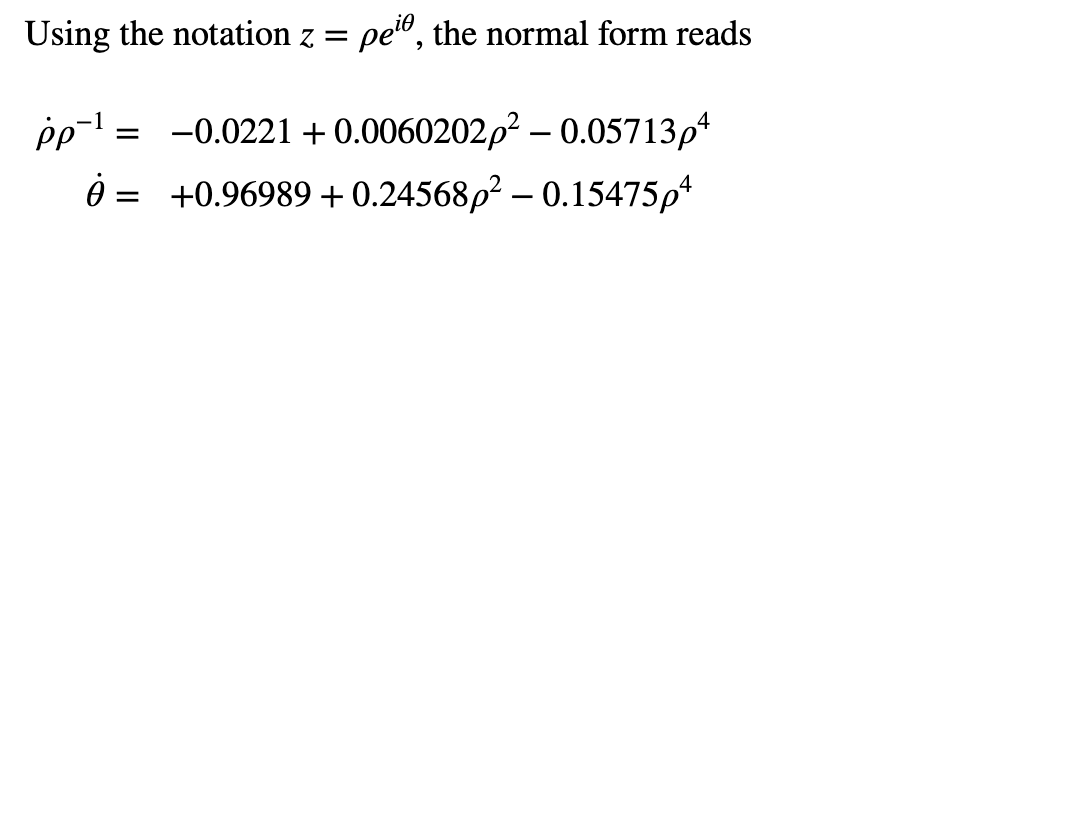


% manifold reduced dynamics 
ROMOrder = 5;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform');

## Backbone curves

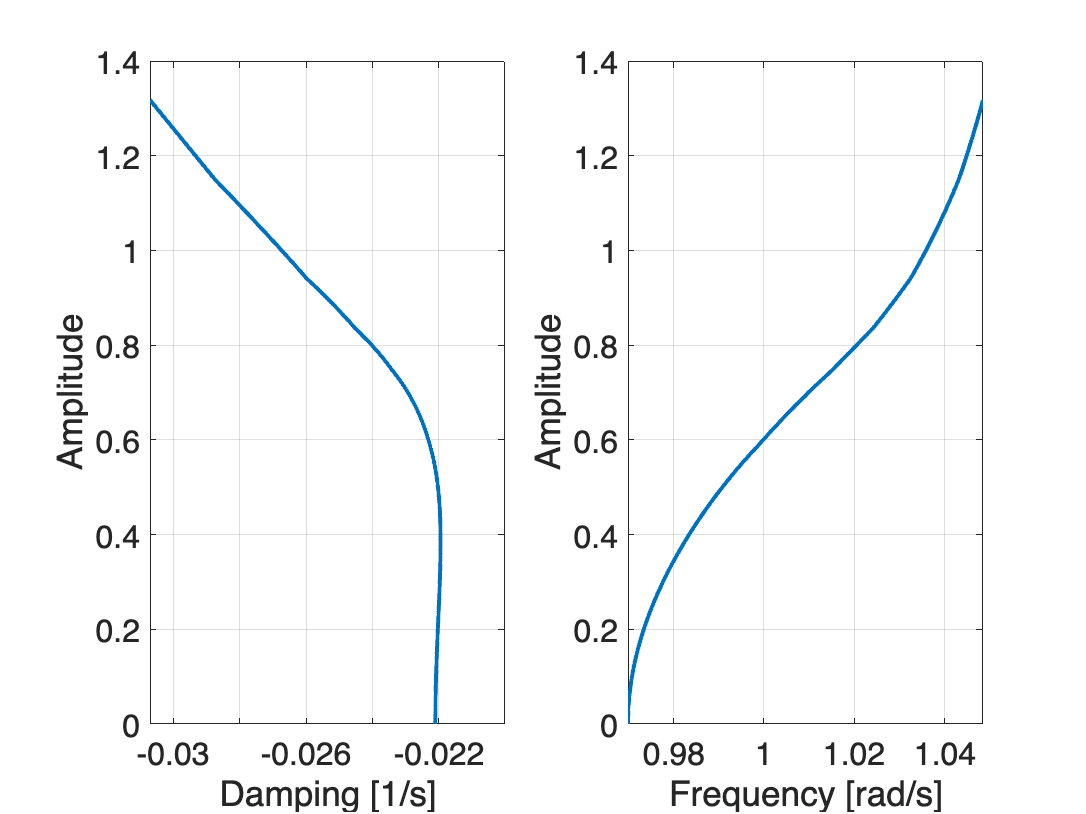

omega_0 = imag(lambda_t(1));
zData = transformTrajectories(RDInfo.inverseTransformation.map, etaData);
rhoCal = abs(zData{indTest(1),2}(1,1));
amplitudeFunction = @(x) x(1,:);
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, rhoCal);

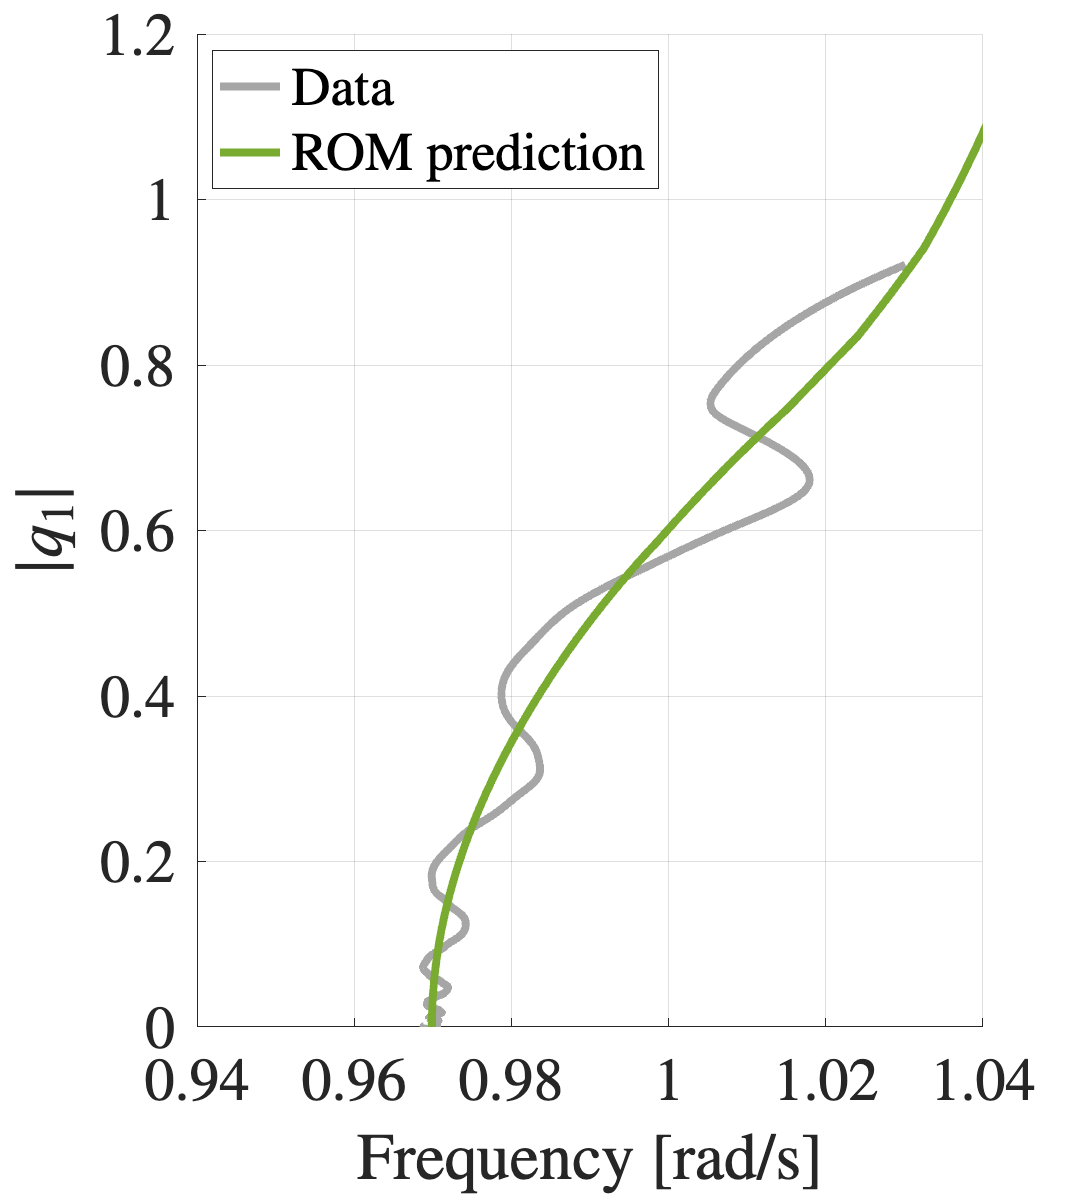


fig = figure;
fig.Position = [476,255,560,617];
hold on 
grid on 
plot(freq_spline_off, amp_spline_off,'Color',[0.65,0.65,0.65],'LineWidth',4,'DisplayName','Data')
plot(BBCInfo.frequency, BBCInfo.amplitude,'color',[0.47,0.67,0.19],'LineWidth',4,'Displayname','ROM prediction')
xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('$|q_1|$','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelInterpreter','Latex', ...
    'OuterPosition',[0,0,1,1.05]);
xlim([0.94 1.04])
legend('location','NW','Interpreter','latex')

## Forced response curves


fig = figure;
fig.Position = [476,255,560,617];
hold on 
grid on 
plot(freq_spline_off, amp_spline_off,'Color',[0.65,0.65,0.65],'LineWidth',4,'DisplayName','Backbone from data')

xlabel('Frequency [rad/s]','Interpreter','Latex')
ylabel('$|q_1|$','Interpreter','Latex')
set(gca,'FontSize',30,'TickLabelInterpreter','Latex', ...
    'OuterPosition',[0,0,1,1.05]);
xlim([0.96 1.02])
legend('location','NW','Interpreter','latex')

omegaSpan_bottom = 0.96;
omegaSpan_top = 1.02;


% FRC from the reduced order model 
amp_lim = 1;

% the amplitude of the forced reduced-order model in physical coordinates
% is taken as the amplitude for which the corresponding force response 
% curve of the full system intersects the backbone curve

amplitudeCal = [0.056 0.138 0.27 0.405 0.538 0.663]; 

forcingSpan = zeros(1,length(amplitudeCal));
for iCal = 1:length(amplitudeCal)
   [~,pos] = min(abs(BBCInfo.amplitude-amplitudeCal(iCal)));
   forcingSpan(iCal) = -BBCInfo.amplitudeNormalForm(pos)*BBCInfo.damping(pos);
end
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


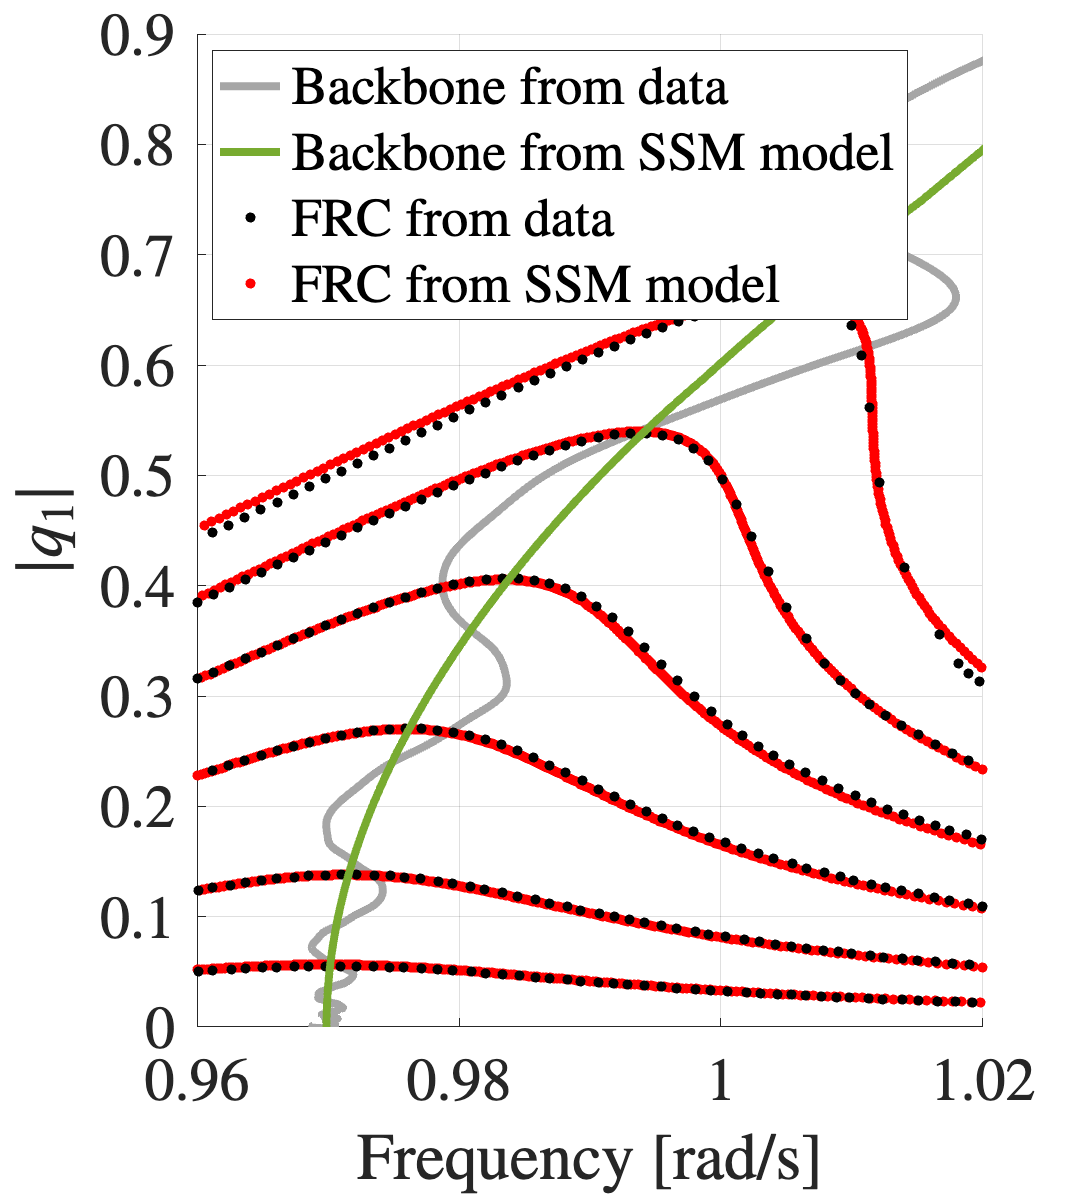

FRCData = analyticalFRC(IMInfoF,RDInfoF,forcingSpan,amplitudeFunction);

for ii = 1:length(amplitudeCal)
    
    forced_freq = FRCData.(['F' num2str(ii)]).Freq(:);
    forced_amp = FRCData.(['F' num2str(ii)]).Amp(:);
    
    index_plot = find(forced_freq>=omegaSpan_bottom & forced_freq<=omegaSpan_top & forced_amp<amp_lim);
    forced_freq_plot = forced_freq(index_plot);
    forced_amp_plot = forced_amp(index_plot);
    
    if ii == 1
        plot(forced_freq_plot, forced_amp_plot,'.r','LineWidth',1,'MarkerSize',15,'DisplayName','FRC from SSM model')
    else
        plot(forced_freq_plot, forced_amp_plot,'.r','LineWidth',1,'MarkerSize',15,'HandleVisibility','off')
    end

end


% generate forced response curves from the original system 
freq_vect = linspace(omegaSpan_bottom,omegaSpan_top,50);
amp_vect = [0.001 0.0025 0.0049 0.0074 0.00987 0.0123];

for jj = 1:length(amp_vect)
    ampl_FRC = zeros(size(freq_vect));
    freq_FRC = zeros(size(freq_vect));
    amp_curr = amp_vect(jj);
    for ii = 1:length(freq_vect)
        Omega = freq_vect(ii);
        F_forced = @(t,x) F_t(t,x) + amp_curr * cos(Omega*t) * [zeros(3,1);1;1;1];
        [t_forced, x_forced] = ode45(F_forced, tSpan_decay, x0_ssm_t);
        t_forced = transpose(t_forced);
        x_forced = transpose(x_forced);
        
        signal = x_forced;
        data = cell(1,2);
        data{1,1} = t_forced;
        data{1,2} = signal;

        kmean = 1;
        [amp_frc,freq_frc,~,~] = PFFk(data{1,1},data{1,2}(1,:),kmean);
        amp_frc = amp_frc(~isnan(freq_frc));
        freq_frc = freq_frc(~isnan(freq_frc));
        ampl_FRC(ii) = amp_frc(end);
        freq_FRC(ii) = 2*pi*freq_frc(end);
        
 
    end
    
    if jj == 1
        plot(freq_FRC, ampl_FRC,'k.','LineWidth',1,'MarkerSize',15,'DisplayName','FRC from data')
    else
        plot(freq_FRC, ampl_FRC,'k.','LineWidth',1,'MarkerSize',15,'HandleVisibility','off')
    end

end

plot(BBCInfo.frequency, BBCInfo.amplitude,'color',[0.47,0.67,0.19],'LineWidth',4,'Displayname','Backbone from SSM model')

h = get(gca,'Children');
legend([h(4) h(1) h(2) h(3)]);

## Additional functions 

function [F,A,M,C,K,F_nl,f_nl] = SP(k1,k2,c1,c2,alpha,epsilon,Omega)

M = eye(2);
C = [c1 + c2, -c2;
    -c2, c1+c2];
K = [k1 + k2, -k2;
    -k2, k1+k2];

f_nl = @(t,x) [alpha * x(1).^3; 0];
f_ext = @(t,x) [epsilon * cos(Omega * t); 0];

A = [zeros(2) eye(2);
    -M\K -M\C];

F_nl = @(t,x) [zeros(2,1); -M\f_nl(t,x)] + [zeros(2,1); M\f_ext(t,x)];

F = @(t,x) A * x + [zeros(2,1); -M\f_nl(t,x)] + [zeros(2,1); M\f_ext(t,x)];

end

function [F,A,M,C,K,F_nl] = SP_moving_frame(k1,k2,c1,c2,m_f,c_f,k_f,alpha)

[~,~,M_rel,C_rel,K_rel,~,f_nl_rel] = SP(k1,k2,c1,c2,alpha,0,0);
M = [M_rel [1;1]; 0 0 m_f];
C = [C_rel [0;0]; -c1 -c1 c_f];
K = [K_rel [0;0]; -k1 -k1 k_f];
f_nl = @(t,x) [f_nl_rel(t,x); -alpha * x(1).^3];
A = [zeros(3) eye(3);
    -M\K -M\C];
F_nl = @(t,x) [zeros(3,1); -M\f_nl(t,x)];

F = @(t,x) A * x + F_nl(t,x);

end

function plotSSM_ssmtool()

    load('XX_cart.mat','XX');
    load('YY_cart.mat','YY');
    load('ZZ_cart.mat','ZZ');
    
end


function [freq_fit_spline, amp_fit_spline] = bc_spline(freq, amp, lim)
    freq_spline = flip(2*pi*freq(amp>lim));
    amp_spline = flip(amp(amp>lim));
    amp_spline = amp_spline(~isnan(freq_spline));
    freq_spline = freq_spline(~isnan(freq_spline));
    amp_fit_spline = linspace(amp_spline(1),amp_spline(end),1000);
    freq_fit_spline = spline(amp_spline,freq_spline,amp_fit_spline);
end

function [t_t, x_t, t_t_off, x_t_off, x0_ssm_t, t_t_train2, x_t_train2, t_t_test, x_t_test] = plot_SSMTool(F_t,tSpan_decay,V_t)

rho_train_t = 0.7;
theta_train_t = 0;
ztrain_t = rho_train_t * exp(1i * theta_train_t);
ztrain_t = [ztrain_t; conj(ztrain_t)];
plotSSM_ssmtool
load('x0_ssm_t_cart.mat','x0_ssm_t');
[t_t, x_t] = ode45(F_t, tSpan_decay, x0_ssm_t);
t_t = transpose(t_t);
x_t = transpose(x_t);
ratio_first = 1;
ratio_second = 3;
ratio_third = 1;
x_ssm_t_complex = V_t\x0_ssm_t;
x_ssm_t_complex_mag = abs(x_ssm_t_complex);
x_ssm_t_complex_phase = angle(x_ssm_t_complex);
new_rho = [x_ssm_t_complex_mag(1) * ratio_first; x_ssm_t_complex_mag(2) * ratio_second; x_ssm_t_complex_mag(3) * ratio_third; x_ssm_t_complex_mag(4) * ratio_first; x_ssm_t_complex_mag(5) * ratio_second; x_ssm_t_complex_mag(6) * ratio_third];
new_x_ssm_t_complex = new_rho .* cos(x_ssm_t_complex_phase) + 1i * new_rho .* sin(x_ssm_t_complex_phase);
new_x_ssm_t = V_t * new_x_ssm_t_complex;
x0_t_off = real(new_x_ssm_t);

[t_t_off, x_t_off] = ode45(F_t, tSpan_decay, x0_t_off);
t_t_off = transpose(t_t_off);
x_t_off = transpose(x_t_off);

x0_t_train2 = 0.9 * x0_t_off;
[t_t_train2, x_t_train2] = ode45(F_t, tSpan_decay, x0_t_train2);
t_t_train2 = transpose(t_t_train2);
x_t_train2 = transpose(x_t_train2);

x0_t_test = 1.1 * x0_t_off;
[t_t_test, x_t_test] = ode45(F_t, tSpan_decay, x0_t_test);
t_t_test = transpose(t_t_test);
x_t_test = transpose(x_t_test);

end
